clear all;
m_a = [0 4 7];
m_b = [10 5 5];
m_c = [-2 -5 -5];

K =1000;
D = 3;

sigma_a = [6.5 2.1651 1.25;2.1651 5.125 2.3816;1.25 2.3816 2.375];
sigma_b = [3.0184 0.4331 -1.4481;0.4331 0.9436 -0.6456;-1.4481 -0.6456 1.288];
sigma_c = [6.8928 -1.375 3.1945;-1.375 3.3572 0.6945;3.1945 0.6945 3.75];

A = generate_gdist(K,D,m_a,sigma_a);
A = transform(A,m_a,sigma_a);

B = generate_gdist(K,D,m_b,sigma_b);
B = transform(B,m_b,sigma_b);

C = generate_gdist(K,D,m_c,sigma_c);
C = transform(C,m_c,sigma_c);

**1. Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.**

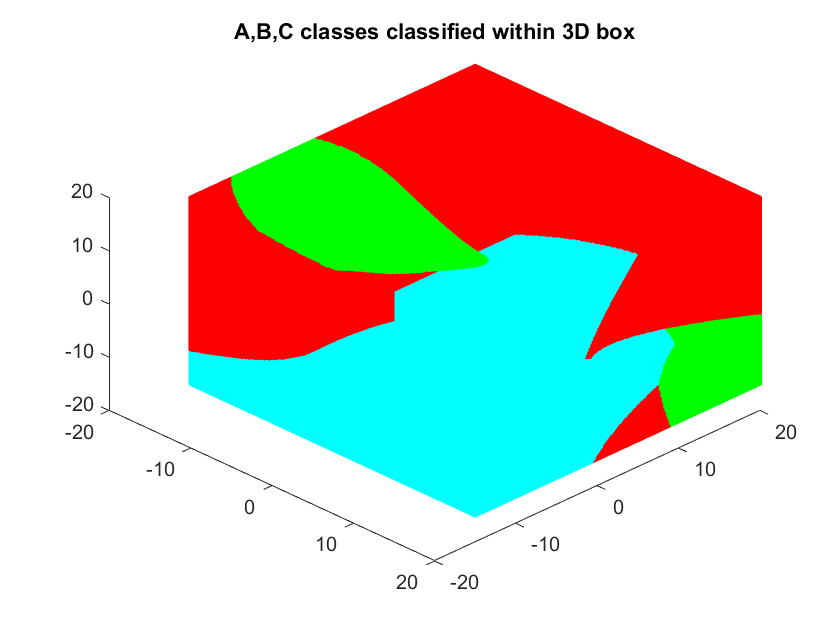

prior_a = 1/3;
prior_b = 1/3;
prior_c = 1/3;

box = vol3D([-15 20 -15 20 -15 20],200);
[row,col] = size(box);

[a,b,c,bound1,bound2] = bayes_bound(m_a,sigma_a,prior_a,m_b,sigma_b,prior_b,m_c,sigma_c,prior_c,box);

plot_box(a,b,c);
title('A,B,C classes classified within 3D box')


plot_classes(A,B,C,m_a,m_b,m_c,sigma_a,sigma_b,sigma_c);

ans =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.9955    1.1519    1.1955    1.1221    0.9388    0.6637    0.3236   -0.0482   -0.4153   -0.7417   -0.9956   -1.1519   -1.1955   -1.1221   -0.9389   -0.6637   -0.3236    0.0482    0.4153    0.7417    0.9955
    1.9666    2.2754    2.3616    2.2166    1.8546    1.3110    0.6392   -0.0953   -0.8204   -1.4652   -1.9666   -2.2755   -2.3616   -2.2166   -1.8546   -1.3111   -0.6392    0.0952    0.8204    1.4652    1.9666
    2.8892    3.3430    3.4695    3.2565    2.7246    1.9261    0.9390   -0.1400   -1.2053   -2.1526   -2.8892   -3.3430   -3.4696   -3.2565   -2.7247   -1.9261   -0.9391    0.1399    1.2052    2.1526    2.8892
    3.7406    4.3282    4.4920    4.2162    3.5276    2.4937    1.2158   -0.1812   -1.5605   -2.7870   -3.7407   -4.3282   -4.4921   -4.2162   -3.5276

ans =     9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075
   10.2988   10.1967   10.0278    9.8085    9.5604    9.3077    9.0752    8.8855    8.7574    8.7032    8.7284    8.8305    8.9994    9.2187    9.4668    9.7195    9.9520   10.1417   10.2698   10.3239   10.2988
   11.0826   10.8810   10.5474   10.1143    9.6241    9.1249    8.6656    8.2910    8.0378    7.9309    7.9807    8.1822    8.5159    8.9490    9.4391    9.9383   10.3977   10.7723   11.0254   11.1324   11.0826
   11.8398   11.5437   11.0534   10.4172    9.6971    8.9637    8.2888    7.7385    7.3666    7.2095    7.2826    7.5788    8.0690    8.7053    9.4253   10.1587   10.8336   11.3839   11.7558   11.9129   11.8398
   12.5517   12.1683   11.5336   10.7098    9.7775    8.8280    7.9542    7.2417    6.7602    6.5568    6.6515    7.0349    7.6696    8.4934    9.4257

ans =    -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
   -2.2798   -2.3811   -2.5901   -2.8864   -3.2409   -3.6190   -3.9837   -4.2991   -4.5346   -4.6670   -4.6833   -4.5820   -4.3730   -4.0767   -3.7222   -3.3441   -2.9795   -2.6640   -2.4286   -2.2962   -2.2798
   -1.0528   -1.2528   -1.6657   -2.2510   -2.9513   -3.6981   -4.4184   -5.0416   -5.5067   -5.7682   -5.8005   -5.6004   -5.1875   -4.6023   -3.9020   -3.1551   -2.4348   -1.8116   -1.3465   -1.0850   -1.0528
    0.1510   -0.1430   -0.7495   -1.6093   -2.6382   -3.7354   -4.7936   -5.7092   -6.3925   -6.7767   -6.8241   -6.5301   -5.9236   -5.0638   -4.0349   -2.9376   -1.8795   -0.9639   -0.2806    0.1036    0.1510
    1.3018    0.9212    0.1359   -0.9773   -2.3094   -3.7300   -5.1001   -6.2854   -7.1701   -7.6675   -7.7289   -7.3483   -6.5630   -5.4498   -4.1177

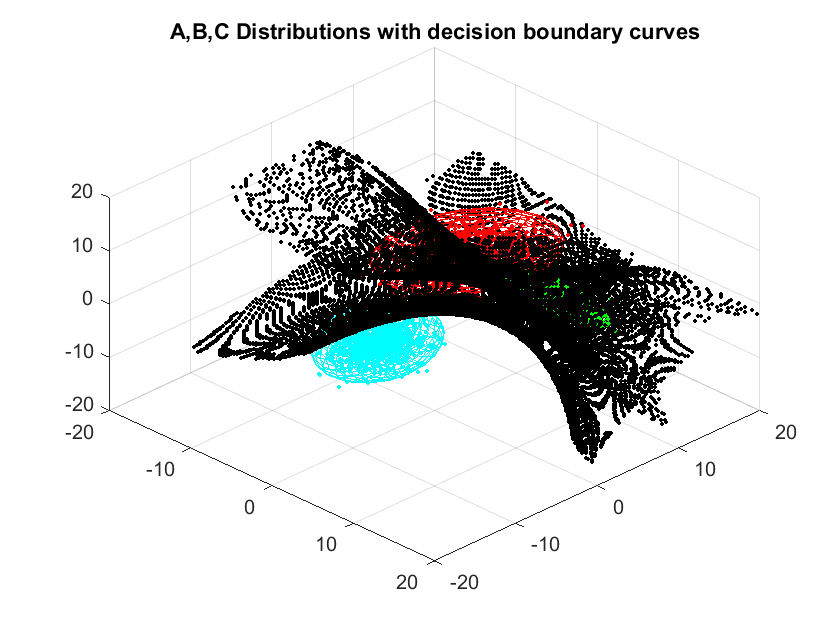


plot_boundaries(bound1,bound2,[0 0 0])
title('A,B,C Distributions with decision boundary curves')

**2. Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.**

**Approach 1 - Interchanging the covariances of classes A, B, C (Covariance significantly changed)**

A : `mean (adding 1)`

`     0+1     4+1     7+1`

`covariance (Covariance of C)`

`    6.8928   -1.3750    3.1945`

`   -1.3750    3.3572    0.6945`

`    3.1945    0.6945    3.7500`

B : `mean`

`    10     5     5`

`covariance (Covariance of A)`

`    6.5000    2.1651    1.2500`

`    2.1651    5.1250    2.3816`

`    1.2500    2.3816    2.3750`

C : mean (adding -1)

`    -2-1    -5-1    -5-1`

`covariance (covariance of B)`

`    3.0184    0.4331   -1.4481`

`    0.4331    0.9436   -0.6456`

`   -1.4481   -0.6456    1.2880`

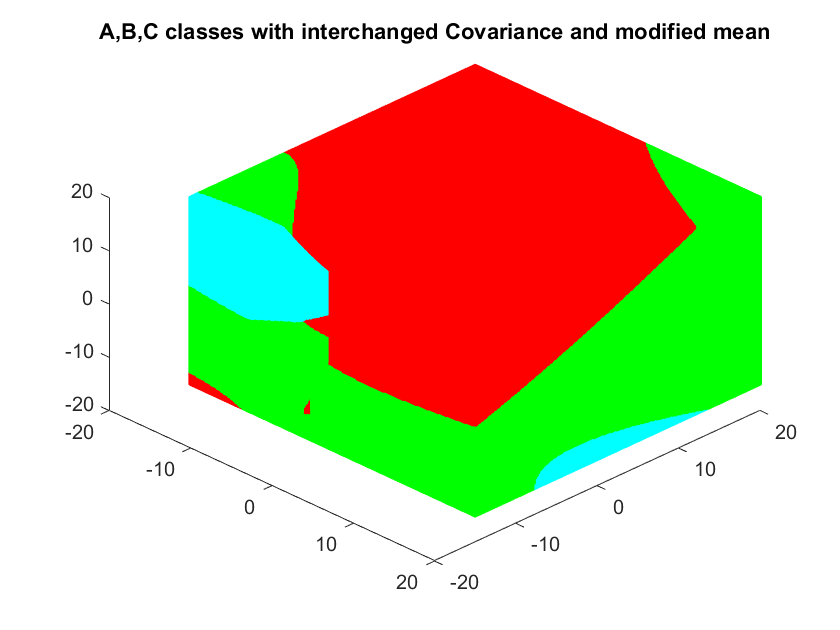

m_a_new_1 = m_a -1;
m_b_new_1 = m_b; 
m_c_new_1 = m_c +1;

sigma_a_new_1 = sigma_c;
sigma_b_new_1 = sigma_a;
sigma_c_new_1 = sigma_b;

A_new_1 = generate_gdist(1000,3,m_a_new_1,sigma_a_new_1);
B_new_1 = generate_gdist(1000,3,m_b_new_1,sigma_b_new_1);
C_new_1 = generate_gdist(1000,3,m_c_new_1,sigma_c_new_1);

A_new_1 = transform(A_new_1,m_a_new_1,sigma_a_new_1);
B_new_1 = transform(B_new_1,m_b_new_1,sigma_b_new_1);
C_new_1 = transform(C_new_1,m_c_new_1,sigma_c_new_1);

[a_new_1,b_new_1,c_new_1,bound1_new_1,bound2_new_1] = bayes_bound(m_a_new_1,sigma_a_new_1,prior_a,m_b_new_1,sigma_b_new_1,prior_b,m_c_new_1,sigma_c_new_1,prior_c,box);

plot_box(a_new_1,b_new_1,c_new_1)
title('A,B,C classes with interchanged Covariance and modified mean')


plot_classes(A_new_1,B_new_1,C_new_1,m_a_new_1,m_b_new_1,m_c_new_1,sigma_a_new_1,sigma_b_new_1,sigma_c_new_1);

ans =    -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000   -2.5000
   -1.2798   -1.3811   -1.5901   -1.8864   -2.2409   -2.6190   -2.9837   -3.2991   -3.5346   -3.6670   -3.6833   -3.5820   -3.3730   -3.0767   -2.7222   -2.3441   -1.9795   -1.6640   -1.4286   -1.2962   -1.2798
   -0.0528   -0.2528   -0.6657   -1.2510   -1.9513   -2.6981   -3.4184   -4.0416   -4.5067   -4.7682   -4.8005   -4.6004   -4.1875   -3.6023   -2.9020   -2.1551   -1.4348   -0.8116   -0.3465   -0.0850   -0.0528
    1.1510    0.8570    0.2505   -0.6093   -1.6382   -2.7354   -3.7936   -4.7092   -5.3925   -5.7767   -5.8241   -5.5301   -4.9236   -4.0638   -3.0349   -1.9376   -0.8795    0.0361    0.7194    1.1036    1.1510
    2.3018    1.9212    1.1359    0.0227   -1.3094   -2.7300   -4.1001   -5.2854   -6.1701   -6.6675   -6.7289   -6.3483   -5.5630   -4.4498   -3.1177

ans =    10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000
   10.9955   11.1519   11.1955   11.1221   10.9388   10.6637   10.3236    9.9518    9.5847    9.2583    9.0044    8.8481    8.8045    8.8779    9.0611    9.3363    9.6764   10.0482   10.4153   10.7417   10.9955
   11.9666   12.2754   12.3616   12.2166   11.8546   11.3110   10.6392    9.9047    9.1796    8.5348    8.0334    7.7245    7.6384    7.7834    8.1454    8.6889    9.3608   10.0952   10.8204   11.4652   11.9666
   12.8892   13.3430   13.4695   13.2565   12.7246   11.9261   10.9390    9.8600    8.7947    7.8474    7.1108    6.6570    6.5304    6.7435    7.2753    8.0739    9.0609   10.1399   11.2052   12.1526   12.8892
   13.7406   14.3282   14.4920   14.2162   13.5276   12.4937   11.2158    9.8188    8.4395    7.2130    6.2593    5.6718    5.5079    5.7838    6.4724

ans =    -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925   -1.4925
   -0.7012   -0.8033   -0.9722   -1.1915   -1.4396   -1.6923   -1.9248   -2.1145   -2.2426   -2.2968   -2.2716   -2.1695   -2.0006   -1.7813   -1.5332   -1.2805   -1.0480   -0.8583   -0.7302   -0.6761   -0.7012
    0.0826   -0.1190   -0.4526   -0.8857   -1.3759   -1.8751   -2.3344   -2.7090   -2.9622   -3.0691   -3.0193   -2.8178   -2.4841   -2.0510   -1.5609   -1.0617   -0.6023   -0.2277    0.0254    0.1324    0.0826
    0.8398    0.5437    0.0534   -0.5828   -1.3029   -2.0363   -2.7112   -3.2615   -3.6334   -3.7905   -3.7174   -3.4212   -2.9310   -2.2947   -1.5747   -0.8413   -0.1664    0.3839    0.7558    0.9129    0.8398
    1.5517    1.1683    0.5336   -0.2902   -1.2225   -2.1720   -3.0458   -3.7583   -4.2398   -4.4432   -4.3485   -3.9651   -3.3304   -2.5066   -1.5743

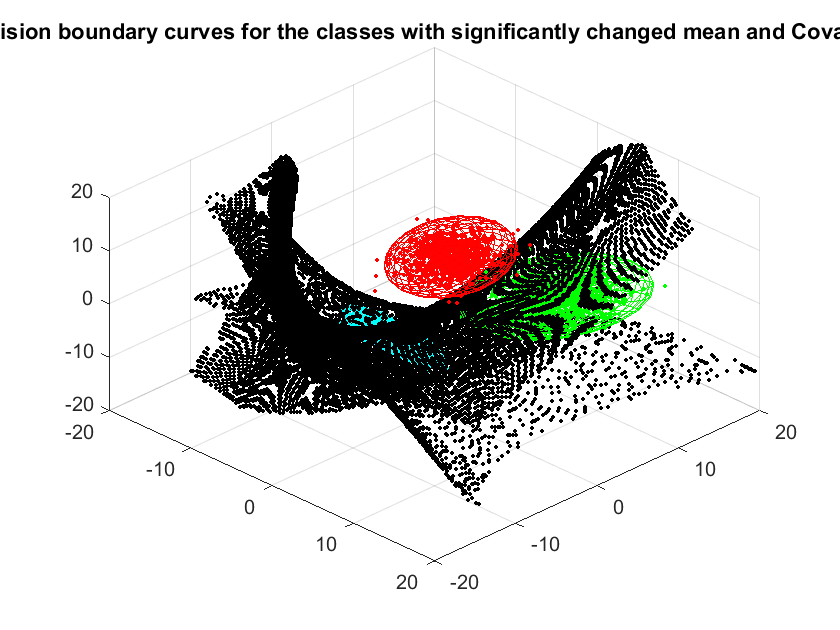


plot_boundaries(bound1_new_1,bound2_new_1,[0 0 0])
title('Decision boundary curves for the classes with significantly changed mean and Covariance')

**Approach 2 - Considering the mean and covariance of classes A, B, C which are obtained before implementing whitening transform. (Covariance and mean close to the original mean and Covariance)**

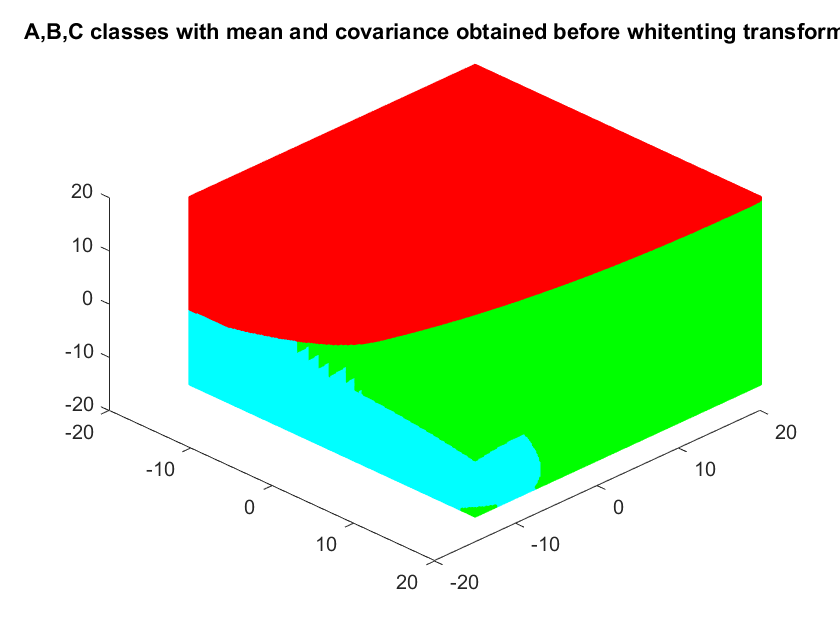

m_a_new_2 = m_a;
m_b_new_2 = m_b; 
m_c_new_2 = m_c;

sigma_a_new_2 = sigma_c;
sigma_b_new_2 = sigma_a;
sigma_c_new_2 = sigma_b;

A_new_2 = generate_gdist(1000,3,m_a_new_2,sigma_a_new_2);
B_new_2 = generate_gdist(1000,3,m_b_new_2,sigma_b_new_2);
C_new_2 = generate_gdist(1000,3,m_c_new_2,sigma_c_new_2);

m_a_new_2 = mean(A_new_2);
m_b_new_2 = mean(B_new_2);
m_c_new_2 = mean(C_new_2);

sigma_a_new_2 = cov(A_new_2);
sigma_b_new_2 = cov(B_new_2);
sigma_c_new_2 = cov(C_new_2);

[a_new_2,b_new_2,c_new_2,bound1_new_2,bound2_new_2] = bayes_bound(m_a_new_2,sigma_a_new_2,prior_a,m_b_new_2,sigma_b_new_2,prior_b,m_c_new_2,sigma_c_new_2,prior_c,box);

plot_box(a_new_2,b_new_2,c_new_2)
title('A,B,C classes with mean and covariance obtained before whitenting transform')


plot_classes(A_new_2,B_new_2,C_new_2,m_a_new_2,m_b_new_2,m_c_new_2,sigma_a_new_2,sigma_b_new_2,sigma_c_new_2);

ans =    -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936   -0.1936
    1.2306    1.1730    0.9818    0.6756    0.2844   -0.1535   -0.5952   -0.9976   -1.3212   -1.5343   -1.6161   -1.5586   -1.3674   -1.0612   -0.6700   -0.2321    0.2097    0.6120    0.9356    1.1487    1.2306
    2.6212    2.5076    2.1298    1.5250    0.7522   -0.1128   -0.9854   -1.7803   -2.4195   -2.8405   -3.0021   -2.8884   -2.5107   -1.9059   -1.1331   -0.2681    0.6046    1.3994    2.0386    2.4596    2.6212
    3.9441    3.7772    3.2222    2.3336    1.1983   -0.0725   -1.3546   -2.5223   -3.4613   -4.0798   -4.3173   -4.1503   -3.5954   -2.7068   -1.5715   -0.3006    0.9814    2.1491    3.0882    3.7067    3.9441
    5.1667    4.9506    4.2321    3.0816    1.6117   -0.0337   -1.6935   -3.2054   -4.4212   -5.2220   -5.5293   -5.3132   -4.5948   -3.4443   -1.9744

ans =    10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344   10.0344
   11.4733   11.4355   11.2605   10.9656   10.5794   10.1399    9.6900    9.2738    8.9321    8.6982    8.5951    8.6329    8.8078    9.1028    9.4890    9.9285   10.3784   10.7946   11.1363   11.3702   11.4733
   12.8763   12.8017   12.4561   11.8734   11.1106   10.2423    9.3536    8.5315    7.8565    7.3945    7.1909    7.2655    7.6111    8.1938    8.9566    9.8248   10.7135   11.5356   12.2107   12.6727   12.8763
   14.2089   14.0993   13.5916   12.7355   11.6148   10.3392    9.0337    7.8259    6.8341    6.1554    5.8562    5.9658    6.4736    7.3297    8.4503    9.7259   11.0315   12.2393   13.2311   13.9098   14.2089
   15.4384   15.2964   14.6391   13.5307   12.0797   10.4282    8.7379    7.1741    5.8901    5.0113    4.6240    4.7660    5.4233    6.5317    7.9827

ans =    -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910
   -1.0410   -1.0838   -1.2154   -1.4228   -1.6859   -1.9788   -2.2729   -2.5393   -2.7521   -2.8903   -2.9405   -2.8977   -2.7662   -2.5587   -2.2956   -2.0027   -1.7087   -1.4422   -1.2294   -1.0912   -1.0410
   -0.1140   -0.1985   -0.4584   -0.8682   -1.3879   -1.9665   -2.5474   -3.0737   -3.4940   -3.7671   -3.8662   -3.7817   -3.5218   -3.1120   -2.5924   -2.0138   -1.4328   -0.9065   -0.4862   -0.2131   -0.1140
    0.7673    0.6431    0.2613   -0.3408   -1.1042   -1.9543   -2.8077   -3.5810   -4.1985   -4.5997   -4.7453   -4.6212   -4.2394   -3.6373   -2.8738   -2.0238   -1.1703   -0.3970    0.2205    0.6217    0.7673
    1.5811    1.4203    0.9260    0.1464   -0.8420   -1.9426   -3.0475   -4.0487   -4.8482   -5.3676   -5.5562   -5.3954   -4.9011   -4.1215   -3.1331

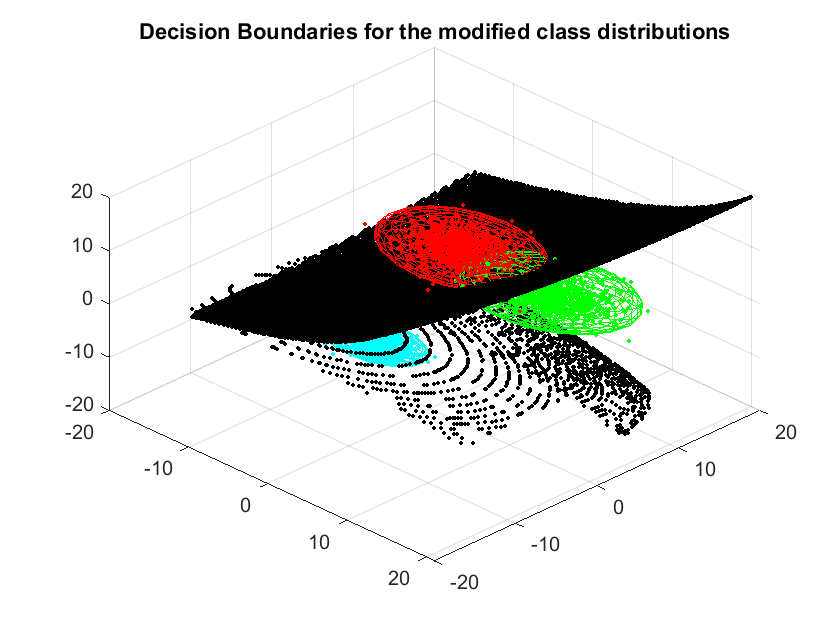


plot_boundaries(bound1_new_2,bound2_new_2,[0 0 0])
title('Decision Boundaries for the modified class distributions')

**3. Show the nature of these changes by plotting the 3 data classes and their respective decision boundaries with the same 3-D plot.**

Plotting the decision boundaries of the modified mean, covariance taken in 2nd que (approach 2) and the distributions A,B,C.

plot_classes(A,B,C,m_a,m_b,m_c,sigma_a,sigma_b,sigma_c);

ans =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.9955    1.1519    1.1955    1.1221    0.9388    0.6637    0.3236   -0.0482   -0.4153   -0.7417   -0.9956   -1.1519   -1.1955   -1.1221   -0.9389   -0.6637   -0.3236    0.0482    0.4153    0.7417    0.9955
    1.9666    2.2754    2.3616    2.2166    1.8546    1.3110    0.6392   -0.0953   -0.8204   -1.4652   -1.9666   -2.2755   -2.3616   -2.2166   -1.8546   -1.3111   -0.6392    0.0952    0.8204    1.4652    1.9666
    2.8892    3.3430    3.4695    3.2565    2.7246    1.9261    0.9390   -0.1400   -1.2053   -2.1526   -2.8892   -3.3430   -3.4696   -3.2565   -2.7247   -1.9261   -0.9391    0.1399    1.2052    2.1526    2.8892
    3.7406    4.3282    4.4920    4.2162    3.5276    2.4937    1.2158   -0.1812   -1.5605   -2.7870   -3.7407   -4.3282   -4.4921   -4.2162   -3.5276

ans =     9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075
   10.2988   10.1967   10.0278    9.8085    9.5604    9.3077    9.0752    8.8855    8.7574    8.7032    8.7284    8.8305    8.9994    9.2187    9.4668    9.7195    9.9520   10.1417   10.2698   10.3239   10.2988
   11.0826   10.8810   10.5474   10.1143    9.6241    9.1249    8.6656    8.2910    8.0378    7.9309    7.9807    8.1822    8.5159    8.9490    9.4391    9.9383   10.3977   10.7723   11.0254   11.1324   11.0826
   11.8398   11.5437   11.0534   10.4172    9.6971    8.9637    8.2888    7.7385    7.3666    7.2095    7.2826    7.5788    8.0690    8.7053    9.4253   10.1587   10.8336   11.3839   11.7558   11.9129   11.8398
   12.5517   12.1683   11.5336   10.7098    9.7775    8.8280    7.9542    7.2417    6.7602    6.5568    6.6515    7.0349    7.6696    8.4934    9.4257

ans =    -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
   -2.2798   -2.3811   -2.5901   -2.8864   -3.2409   -3.6190   -3.9837   -4.2991   -4.5346   -4.6670   -4.6833   -4.5820   -4.3730   -4.0767   -3.7222   -3.3441   -2.9795   -2.6640   -2.4286   -2.2962   -2.2798
   -1.0528   -1.2528   -1.6657   -2.2510   -2.9513   -3.6981   -4.4184   -5.0416   -5.5067   -5.7682   -5.8005   -5.6004   -5.1875   -4.6023   -3.9020   -3.1551   -2.4348   -1.8116   -1.3465   -1.0850   -1.0528
    0.1510   -0.1430   -0.7495   -1.6093   -2.6382   -3.7354   -4.7936   -5.7092   -6.3925   -6.7767   -6.8241   -6.5301   -5.9236   -5.0638   -4.0349   -2.9376   -1.8795   -0.9639   -0.2806    0.1036    0.1510
    1.3018    0.9212    0.1359   -0.9773   -2.3094   -3.7300   -5.1001   -6.2854   -7.1701   -7.6675   -7.7289   -7.3483   -6.5630   -5.4498   -4.1177

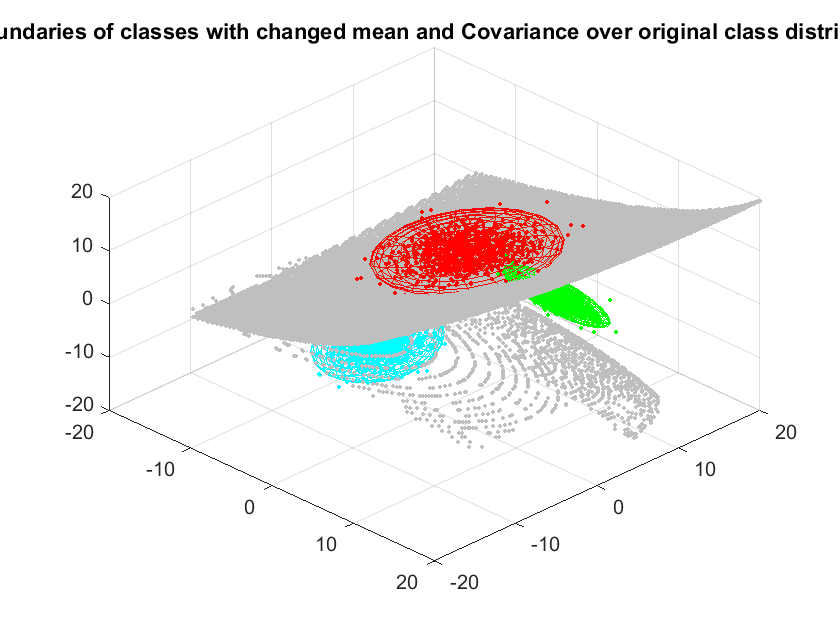


plot_boundaries(bound1_new_2,bound2_new_2,[0.75 0.75 0.75])
title('Decision boundaries of classes with changed mean and Covariance over original class distributions (A,B,C)')
hold off

**4. Assess how these decision boundaries change with changes to the three class's a priori probabilities.**

**1.**prior_a = 0.9

   prior_b = 0.05

   prior_c = 0.05

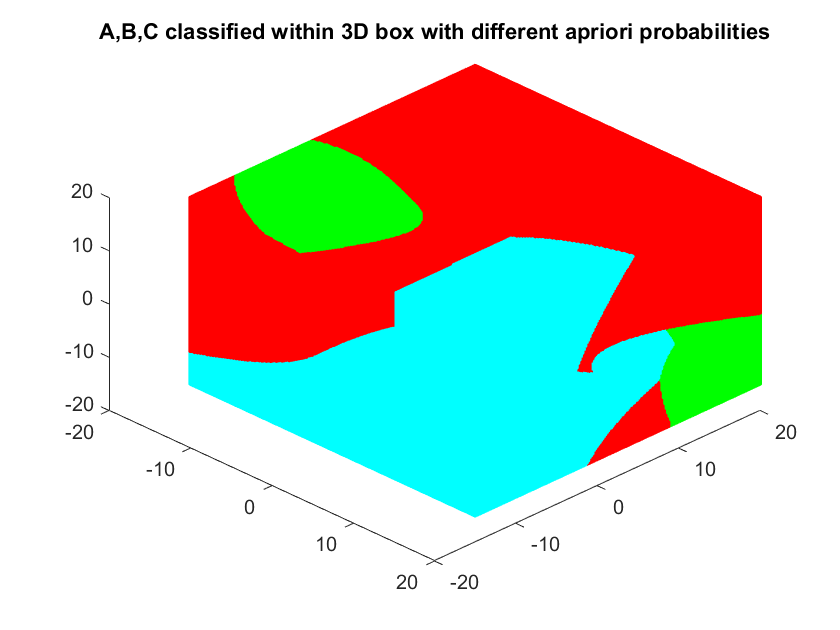

prior_a_1 = 0.9;
prior_b_1 = 0.05;
prior_c_1 = 0.05;
[a_1,b_1,c_1,bound1_1,bound2_1] = bayes_bound(m_a,sigma_a,prior_a_1,m_b,sigma_b,prior_b_1,m_c,sigma_c,prior_c_1,box);

plot_box(a_1,b_1,c_1)
title('A,B,C classified within 3D box with different apriori probabilities')


plot_classes(A,B,C,m_a,m_b,m_c,sigma_a,sigma_b,sigma_c);

ans =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.9955    1.1519    1.1955    1.1221    0.9388    0.6637    0.3236   -0.0482   -0.4153   -0.7417   -0.9956   -1.1519   -1.1955   -1.1221   -0.9389   -0.6637   -0.3236    0.0482    0.4153    0.7417    0.9955
    1.9666    2.2754    2.3616    2.2166    1.8546    1.3110    0.6392   -0.0953   -0.8204   -1.4652   -1.9666   -2.2755   -2.3616   -2.2166   -1.8546   -1.3111   -0.6392    0.0952    0.8204    1.4652    1.9666
    2.8892    3.3430    3.4695    3.2565    2.7246    1.9261    0.9390   -0.1400   -1.2053   -2.1526   -2.8892   -3.3430   -3.4696   -3.2565   -2.7247   -1.9261   -0.9391    0.1399    1.2052    2.1526    2.8892
    3.7406    4.3282    4.4920    4.2162    3.5276    2.4937    1.2158   -0.1812   -1.5605   -2.7870   -3.7407   -4.3282   -4.4921   -4.2162   -3.5276

ans =     9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075    9.5075
   10.2988   10.1967   10.0278    9.8085    9.5604    9.3077    9.0752    8.8855    8.7574    8.7032    8.7284    8.8305    8.9994    9.2187    9.4668    9.7195    9.9520   10.1417   10.2698   10.3239   10.2988
   11.0826   10.8810   10.5474   10.1143    9.6241    9.1249    8.6656    8.2910    8.0378    7.9309    7.9807    8.1822    8.5159    8.9490    9.4391    9.9383   10.3977   10.7723   11.0254   11.1324   11.0826
   11.8398   11.5437   11.0534   10.4172    9.6971    8.9637    8.2888    7.7385    7.3666    7.2095    7.2826    7.5788    8.0690    8.7053    9.4253   10.1587   10.8336   11.3839   11.7558   11.9129   11.8398
   12.5517   12.1683   11.5336   10.7098    9.7775    8.8280    7.9542    7.2417    6.7602    6.5568    6.6515    7.0349    7.6696    8.4934    9.4257

ans =    -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
   -2.2798   -2.3811   -2.5901   -2.8864   -3.2409   -3.6190   -3.9837   -4.2991   -4.5346   -4.6670   -4.6833   -4.5820   -4.3730   -4.0767   -3.7222   -3.3441   -2.9795   -2.6640   -2.4286   -2.2962   -2.2798
   -1.0528   -1.2528   -1.6657   -2.2510   -2.9513   -3.6981   -4.4184   -5.0416   -5.5067   -5.7682   -5.8005   -5.6004   -5.1875   -4.6023   -3.9020   -3.1551   -2.4348   -1.8116   -1.3465   -1.0850   -1.0528
    0.1510   -0.1430   -0.7495   -1.6093   -2.6382   -3.7354   -4.7936   -5.7092   -6.3925   -6.7767   -6.8241   -6.5301   -5.9236   -5.0638   -4.0349   -2.9376   -1.8795   -0.9639   -0.2806    0.1036    0.1510
    1.3018    0.9212    0.1359   -0.9773   -2.3094   -3.7300   -5.1001   -6.2854   -7.1701   -7.6675   -7.7289   -7.3483   -6.5630   -5.4498   -4.1177

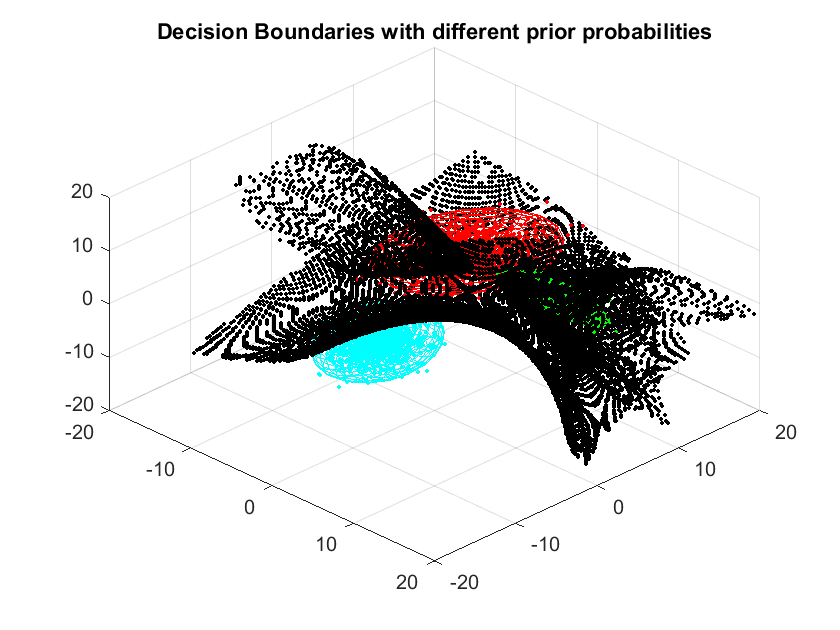


plot_boundaries(bound1_1,bound2_1,[0 0 0]);
title('Decision Boundaries with different prior probabilities')

**5. Assess how these decision boundaries change with changes to the classes loss functions**

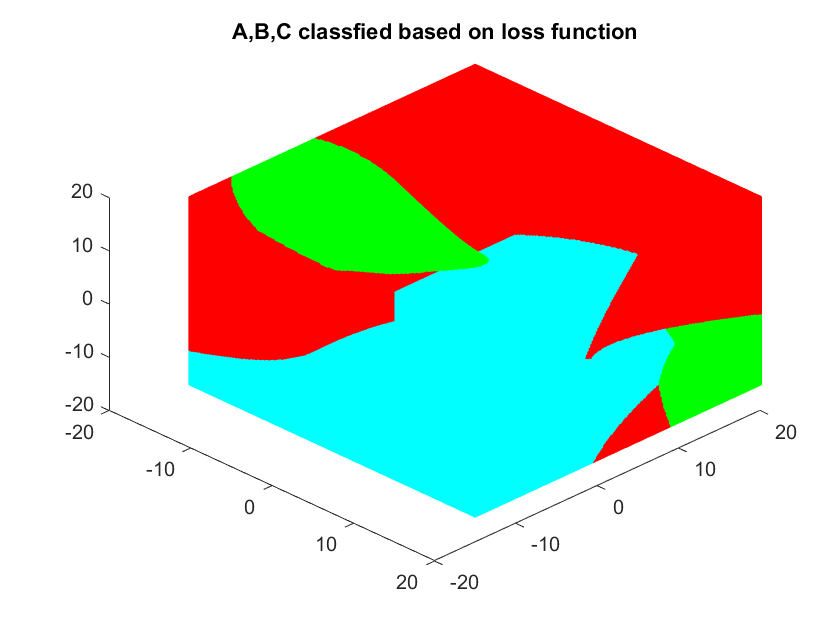

p_a_x = post_prob(m_a,sigma_a,3,box);
p_b_x = post_prob(m_b,sigma_b,3,box);
p_c_x = post_prob(m_c,sigma_c,3,box);

p_probs = [p_a_x p_b_x p_c_x];

p_probs = p_probs.';

loss_a = [0 1 1];
loss_b = [1 0 1];
loss_c = [1 1 0];

r_a = loss_fn(loss_a, p_probs);  
r_b = loss_fn(loss_b, p_probs); 
r_c = loss_fn(loss_c, p_probs);

g_a_r = -r_a;
g_b_r = -r_b;
g_c_r = -r_c;

g_r =[g_a_r ;g_b_r ;g_c_r];

[a_r,b_r,c_r,dbound1,dbound2] = classify(g_r,box);

plot_box(a_r,b_r,c_r)
title('A,B,C classfied based on loss function')


% plot_classes(A,B,C,m_a,m_b,m_c,sigma_a,sigma_b,sigma_c);
% plot_boundaries(dbound1,dbound2,[0 0 0])



function [a,b,c,bound1, bound2] = bayes_bound(m_a,sigma_a,prior_a,m_b,sigma_b,prior_b,m_c,sigma_c,prior_c,box)
    g_a = discriminant_fn(m_a,sigma_a,prior_a,box);
    g_b = discriminant_fn(m_b,sigma_b,prior_b,box);
    g_c = discriminant_fn(m_c,sigma_c,prior_c,box);
    
    g = [g_a g_b g_c];
    g = g.';
    
    [a,b,c,bound1,bound2] = classify(g,box);

end

function [a,b,c,bound1,bound2] = classify(disc_fn,box)
 
    [M,I] = max(disc_fn);  

    ind_a = find(I==1); 
    ind_b = find(I==2);
    ind_c = find(I==3);
    
    a = box(ind_a,:);
    b = box(ind_b,:);
    c = box(ind_c,:);
    
    db1 = abs(disc_fn(1,:)-disc_fn(2,:)); 
    db2 = abs(disc_fn(1,:)-disc_fn(3,:));
    
    ind_bound_1 = find(db1<0.1);
    
    ind_bound_2 = find(db2<0.1);
    
    bound1 = box(ind_bound_1,:);
    bound2 = box(ind_bound_2,:);
end

function g_x = discriminant_fn(mu,sigma,prior_prob,x) 
    w1 = (-1/2)*inv(sigma);
    
    w2 = inv(sigma)*mu';
    
    w3 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma)) + log(prior_prob);
        
    g_x = sum((x*w1.').*x,2).' + w2'*x' + w3;
    
    g_x = g_x.';

end

function [x1,y1,z1] = plot_ellipsoids(mu,sigma,edge_color,sd)
    [E,v] = eigs(sigma);
    std_ = sqrt(diag(v));
    
    [x1,y1,z1] = ellipsoid(0,0,0,sd*std_(1),sd*std_(2),sd*std_(3));
    
    a = kron(E(:,1),x1); 
    b = kron(E(:,2),y1); 
    c = kron(E(:,3),z1);
    d = a+b+c; 
    
    n = size(d,2);
    x1 = d(1:n,:)+mu(1); 
    y1 = d(n+1:2*n,:)+mu(2); 
    z1 = d(2*n+1:end,:)+mu(3);
    
    surf(x1,y1,z1,'FaceAlpha',0.01,'EdgeColor',edge_color);
    
    view([45 45])
end

function [] = plot_box(a,b,c)
    plot3(a(:,1),a(:,2),a(:,3),'Marker',".","LineStyle","none","Color",[1 0 0])
    hold on
    plot3(b(:,1),b(:,2),b(:,3),'Marker',".","LineStyle","none","Color",[0 1 0])
    plot3(c(:,1),c(:,2),c(:,3),'Marker',".","LineStyle","none","Color",[0 1 1])
    hold off
    view([45 45])
end

function [] = plot_classes(A,B,C,m_a,m_b,m_c,sigma_a,sigma_b,sigma_c)
    plot_ellipsoids(m_a,sigma_a,[1 0 0],3)
    hold on
    plot_ellipsoids(m_b,sigma_b,[0 1 0],3)
    plot_ellipsoids(m_c,sigma_c,[0 1 1],3)
    
    scatter3(A(:,1),A(:,2),A(:,3),'r.')
    scatter3(B(:,1),B(:,2),B(:,3),'g.')
    scatter3(C(:,1),C(:,2),C(:,3),'c.')
    
    view([45 45])
end

function [] = plot_boundaries(bound1,bound2,color)
    plot3(bound1(:,1),bound1(:,2),bound1(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(bound2(:,1),bound2(:,2),bound2(:,3),'Marker',".","LineStyle","none","Color",color)
    hold off
    
    view([45 45])
end

function data = generate_gdist(samples,dimensions,m,sigma)
data  = randn(samples,dimensions);
[E,v] = eigs(sigma);
data = v^(1/2) * E * data.';
data = data.' + m;
end

function dist = transform(data,m,sigma)

%%whitening transformation
data = data-mean(data);
[E,v] = eigs(cov(data));
Y = E*v^(-1/2);
X = data * Y;

% X is the distribution around Origin with unit distance between points in corresponding dimensions

%cov(X)          %% identity matrix
%mean(X)         %% zero row-vector (origin)

%%coloring transformation
[E1,v1] = eigs(sigma);
Y = v1^(1/2) * X';
dist = E1 * Y;
dist = dist'+m;
end

function p_w_x = post_prob(mu,sigma,dim,box)
x = box-mu;
y = inv(sigma);
z = sum((x*y.').*x,2).';

p_w_x = (1/(((2*pi)^(dim/2))*(det(sigma))^(1/2)))*exp((-1/2)*z);

p_w_x = p_w_x.';

end

function r = loss_fn(loss,post_probs)
r = loss*post_probs;
end

function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%   
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end

